# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "gen_cost"

objFunction = "gen_cost"

numAreas = 4

numAreas = 4

T = 1

T = 1

macroItrMax = 10; % Max no. of permissible iterations for optimizing an area
noBatteries = false;
alpha = 1e-3;
% gamma = 1e-1;
gamma = 1e0;
% delta_t = 0.25;
delta_t = 1.00; % one hour
DER_percent = 20;
Batt_percent = 20;
displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = false;


% delta_t = 0.25; % 15 minutes = 0.25 hours
delta_t = 1.00;
% globalPVCoeff = 2.3;
globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.4, 'upwards')

lambdaVals = 1.4000

% lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')
loadVals = lambdaVals*3

loadVals = 4.2000

pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)

pvCoeffVals = 0.9000

% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

% costArray0 = [-1.0, 0.0, 0.7, 1.2, 1.5, 1.7, 6.4, 5.4, 2.5, 2.5, 3.2, 3.6, 2.2, 1.9, 1.8, 1.9, 2.9, 5.0, 4.6, 4.5, 4.4, 4.0, 2.8, 4.9]';
costArray0 = [1.6, 3.8, 1.7, 1.8, 2.1, 2.2, 2.4, 2.9, 4.4, 5.1, 4.3, 3.5, 2.8, 2.8, 2.3, 2.0, 2.3, 4.1, 3.4, 6.6, 4.7, 4.7, 5.0, 2.6]';
costArray = choose_middle_T_points(costArray0, T);

V_min = 0.95;
V_max = 1.05;
etta_C = 0.95;
etta_D = 0.95;
soc_min = 0.30;
soc_max = 0.95;

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
elseif strcmp(objFunction, "gen_cost")
    strObjectiveFunction = "Cost of Substation Power";
    suffixObj = "genCost";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;
PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubs_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubs_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubsCost_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubsCost_1toT_vs_macroItr = zeros(T, macroItrMax);

sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;

simInfo = struct();
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.DER_percent = DER_percent;
simInfo.Batt_percent = Batt_percent;
simInfo.etta_C = etta_C;
simInfo.etta_D = etta_D;
simInfo.chargeToPowerRatio = chargeToPowerRatio;
simInfo.soc_min = soc_min;
simInfo.soc_max = soc_max;
simInfo.V_min = V_min;
simInfo.V_max = V_max;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.strObjectiveFunction = strObjectiveFunction;
simInfo.suffixObj = suffixObj;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.costArray = costArray;
simInfo.delta_t = delta_t;
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
Residuals_1toT_vs_macroItr = zeros(2*numRelationships, T, macroItrMax);

while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T)
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        
        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T)
        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
    
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij)'; %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij)'; %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj)'; %N_Areax1
        
        PSubs_Area_1toT = P_Area_1toT(1, 1:T);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        PSubs_allT_vs_macroItr(macroItr+1) = PSubs_allT_vs_macroItr(macroItr+1) + areaInfo.PSubs_allT;
        PSubs_1toT_vs_macroItr(1:T, macroItr+1) = PSubs_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubs_1toT;
        PSubsCost_allT_vs_macroItr(macroItr+1) = PSubsCost_allT_vs_macroItr(macroItr+1) + areaInfo.PSubsCost_allT;
        PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubsCost_1toT;

        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.Ploss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
        sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
        sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
        sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    % first let's quickly compute system losses for the macroItr first and
    % store them
    
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;

            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr-1, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)
                    disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
    
            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =      0
     0


xVals_Area_1toT =     0.1955
    0.1955
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.1543
    0.1491
    0.0257


Macro-iteration 1: Running OPF for Area 2.


v_parAr_1toT = 1.0609

S_chArs_1toT = 0

xVals_Area_1toT =     0.1416
    0.1416
    0.1313
    0.1210
    0.0103
    0.0051
    0.1107
    0.0103
    0.0051
    0.1004


Macro-iteration 1: Running OPF for Area 3.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 1: Running OPF for Area 4.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.3668
    0.3668
    0.3668
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 4.5453e-21 + 5.5949e-21i

S12_intoChild_1toT = 0.1416 - 0.0008i

delta_S12_1toT = -0.1416 + 0.0008i

delta_v_1toT = -0.0041

Macro-iteration 1: Current Biggest Residual is 1.416200e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = -2.2526e-21 - 2.5741e-21i

S12_intoChild_1toT = 0.1941 - 0.0005i

delta_S12_1toT = -0.1941 + 0.0005i

delta_v_1toT = -0.0056

Macro-iteration 1: Current Biggest Residual is 1.941344e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 2.3955e-21 - 2.5186e-21i

S12_intoChild_1toT = 0.3668 - 0.0009i

delta_S12_1toT = -0.3668 + 0.0009i

delta_v_1toT = -0.0042

Macro-iteration 1: Current Biggest Residual is 3.668134e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0568
    1.0609
    1.0609


    1.0568



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1416 - 0.0008i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


   0.1416 - 0.0008i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0568
    1.0553
    1.0609


    1.0553



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1416 - 0.0008i
   0.1941 - 0.0005i
   0.0000 + 0.0000i


   0.1941 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0568
    1.0553
    1.0567


    1.0567



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1416 - 0.0008i
   0.1941 - 0.0005i
   0.3668 - 0.0009i


   0.3668 - 0.0009i



Macro-iteration 2: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.1416 - 0.0008i
   0.1941 - 0.0005i


xVals_Area_1toT =     0.5339
    0.5339
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.4917
    0.4859
    0.0256


Macro-iteration 2: Running OPF for Area 2.


v_parAr_1toT = 1.0568

S_chArs_1toT = 0.3668 - 0.0009i

xVals_Area_1toT =     0.5123
    0.5123
    0.5011
    0.4903
    0.0103
    0.0051
    0.4798
    0.0103
    0.0051
    0.4687


Macro-iteration 2: Running OPF for Area 3.


v_parAr_1toT = 1.0553


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 2: Running OPF for Area 4.


v_parAr_1toT = 1.0567


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.3668
    0.3668
    0.3668
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1416 - 0.0008i

S12_intoChild_1toT = 0.5123 - 0.0070i

delta_S12_1toT = -0.3707 + 0.0062i

delta_v_1toT = -0.0080

Macro-iteration 2: Current Biggest Residual is 3.707502e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1941 - 0.0005i

S12_intoChild_1toT = 0.1941 + 0.0198i

delta_S12_1toT = -0.0000 - 0.0202i

delta_v_1toT = -0.0111

Macro-iteration 2: Current Biggest Residual is 2.021771e-02 at index 1.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3668 - 0.0009i

S12_intoChild_1toT = 0.3668 - 0.0009i

delta_S12_1toT = -2.2367e-06 - 1.0182e-06i

delta_v_1toT = -0.0173

Macro-iteration 2: Current Biggest Residual is 1.732192e-02 at index 2.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0489
    1.0553
    1.0567


    1.0489



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.5123 - 0.0070i
   0.1941 - 0.0005i
   0.3668 - 0.0009i


   0.5123 - 0.0070i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0489
    1.0442
    1.0567


    1.0442



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.5123 - 0.0070i
   0.1941 + 0.0198i
   0.3668 - 0.0009i


   0.1941 + 0.0198i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0489
    1.0442
    1.0394


    1.0394



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.5123 - 0.0070i
   0.1941 + 0.0198i
   0.3668 - 0.0009i


   0.3668 - 0.0009i



Macro-iteration 3: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.5123 - 0.0070i
   0.1941 + 0.0198i


xVals_Area_1toT =     0.9109
    0.9109
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.8667
    0.8594
    0.0257


Macro-iteration 3: Running OPF for Area 2.


v_parAr_1toT = 1.0489

S_chArs_1toT = 0.3668 - 0.0009i

xVals_Area_1toT =     0.5124
    0.5124
    0.5011
    0.4903
    0.0103
    0.0051
    0.4798
    0.0103
    0.0051
    0.4687


Macro-iteration 3: Running OPF for Area 3.


v_parAr_1toT = 1.0442


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 3: Running OPF for Area 4.


v_parAr_1toT = 1.0394


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.3668
    0.3668
    0.3668
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.5123 - 0.0070i

S12_intoChild_1toT = 0.5124 - 0.0070i

delta_S12_1toT = -3.3731e-05 + 6.8515e-05i

delta_v_1toT = -0.0088

Macro-iteration 3: Current Biggest Residual is 8.804167e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1941 + 0.0198i

S12_intoChild_1toT = 0.1941 - 0.0005i

delta_S12_1toT = -0.0000 + 0.0202i

delta_v_1toT = -0.0090

Macro-iteration 3: Current Biggest Residual is 2.022633e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3668 - 0.0009i

S12_intoChild_1toT = 0.3668 - 0.0009i

delta_S12_1toT = -1.6548e-05 + 1.1493e-05i

delta_v_1toT = -0.0080

Macro-iteration 3: Current Biggest Residual is 7.954737e-03 at index 2.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0431
    1.0442
    1.0394


***Macro-iteration 3 Communication Power:****


   0.4938 - 0.0067i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0431
    1.0384
    1.0394


***Macro-iteration 3 Communication Power:****


   0.1941 + 0.0046i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0431
    1.0384
    1.0347


***Macro-iteration 3 Communication Power:****


   0.3668 - 0.0009i



Macro-iteration 4: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4938 - 0.0067i
   0.1941 + 0.0046i


xVals_Area_1toT =     0.8920
    0.8920
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.8479
    0.8408
    0.0257


Macro-iteration 4: Running OPF for Area 2.


v_parAr_1toT = 1.0431

S_chArs_1toT = 0.3668 - 0.0009i

xVals_Area_1toT =     0.5124
    0.5124
    0.5011
    0.4904
    0.0103
    0.0051
    0.4798
    0.0103
    0.0051
    0.4688


Macro-iteration 4: Running OPF for Area 3.


v_parAr_1toT = 1.0384


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 4: Running OPF for Area 4.


v_parAr_1toT = 1.0347


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.3668
    0.3668
    0.3668
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4938 - 0.0067i

S12_intoChild_1toT = 0.5124 - 0.0071i

delta_S12_1toT = -0.0186 + 0.0004i

delta_v_1toT = -0.0026

Macro-iteration 4: Current Biggest Residual is 1.858371e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1941 + 0.0046i

S12_intoChild_1toT = 0.1941 - 0.0005i

delta_S12_1toT = -0.0000 + 0.0051i

delta_v_1toT = -0.0026

Macro-iteration 4: Current Biggest Residual is 5.059497e-03 at index 1.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3668 - 0.0009i

S12_intoChild_1toT = 0.3668 + 0.0000i

delta_S12_1toT = 1.3307e-05 - 9.3912e-04i

delta_v_1toT = -0.0090

Macro-iteration 4: Current Biggest Residual is 9.017564e-03 at index 2.


Macro-iteration 4: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0408
    1.0384
    1.0347


***Macro-iteration 4 Communication Power:****


   0.5124 - 0.0070i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0408
    1.0360
    1.0347


***Macro-iteration 4 Communication Power:****


   0.1941 + 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0408
    1.0360
    1.0278


***Macro-iteration 4 Communication Power:****


   0.3668 - 0.0002i



Macro-iteration 5: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.5124 - 0.0070i
   0.1941 + 0.0005i


xVals_Area_1toT =     0.9110
    0.9110
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.8668
    0.8595
    0.0257


Macro-iteration 5: Running OPF for Area 2.


v_parAr_1toT = 1.0408

S_chArs_1toT = 0.3668 - 0.0002i

xVals_Area_1toT =     0.5124
    0.5124
    0.5011
    0.4904
    0.0103
    0.0051
    0.4798
    0.0103
    0.0051
    0.4688


Macro-iteration 5: Running OPF for Area 3.


v_parAr_1toT = 1.0360


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 5: Running OPF for Area 4.


v_parAr_1toT = 1.0278


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.3668
    0.3668
    0.3668
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.5124 - 0.0070i

S12_intoChild_1toT = 0.5124 - 0.0071i

delta_S12_1toT = -1.1577e-05 + 4.8610e-05i

delta_v_1toT = -7.1158e-04

Macro-iteration 5: Current Biggest Residual is 7.115760e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1941 + 0.0005i

S12_intoChild_1toT = 0.1941 - 0.0005i

delta_S12_1toT = -0.0000 + 0.0010i

delta_v_1toT = -6.3786e-04

Macro-iteration 5: Current Biggest Residual is 1.019046e-03 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3668 - 0.0002i

S12_intoChild_1toT = 0.3668 - 0.0009i

delta_S12_1toT = -2.3436e-05 + 6.7794e-04i

delta_v_1toT = -0.0044

Macro-iteration 5: Current Biggest Residual is 4.384898e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 5: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 5 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 5 Communication Voltage:****


v1_1toT =     1.0609
    1.0402
    1.0360
    1.0278


***Macro-iteration 5 Communication Power:****


   0.5124 - 0.0071i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 5 Communication Voltage:****


v1_1toT =     1.0609
    1.0402
    1.0355
    1.0278


***Macro-iteration 5 Communication Power:****


   0.1941 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 5 Communication Voltage:****


v1_1toT =     1.0609
    1.0402
    1.0355
    1.0244


***Macro-iteration 5 Communication Power:****


   0.3668 - 0.0007i



Macro-iteration 6: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.5124 - 0.0071i
   0.1941 - 0.0005i


xVals_Area_1toT =     0.9109
    0.9109
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.8668
    0.8595
    0.0257


Macro-iteration 6: Running OPF for Area 2.


v_parAr_1toT = 1.0402

S_chArs_1toT = 0.3668 - 0.0007i

xVals_Area_1toT =     0.5124
    0.5124
    0.5011
    0.4904
    0.0103
    0.0051
    0.4798
    0.0103
    0.0051
    0.4688


Macro-iteration 6: Running OPF for Area 3.


v_parAr_1toT = 1.0355


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT =     0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 6: Running OPF for Area 4.


v_parAr_1toT = 1.0244


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT = 393×1
    0.3669
    0.3669
    0.3669
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 6: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.5124 - 0.0071i

S12_intoChild_1toT = 0.5124 - 0.0071i

delta_S12_1toT = -1.8878e-05 + 2.4866e-06i

delta_v_1toT = -5.2255e-05

Macro-iteration 6: Current Biggest Residual is 5.225497e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1941 - 0.0005i

S12_intoChild_1toT = 0.1941 - 0.0005i

delta_S12_1toT = 8.0938e-08 - 1.3907e-05i

delta_v_1toT = 5.5420e-05

Macro-iteration 6: Current Biggest Residual is 5.541985e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3668 - 0.0007i

S12_intoChild_1toT = 0.3669 - 0.0009i

delta_S12_1toT = -9.7022e-06 + 2.4981e-04i

delta_v_1toT = -0.0016

Macro-iteration 6: Current Biggest Residual is 1.576177e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 6: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 6 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 6 Communication Voltage:****


v1_1toT = 4×1
    1.0609
    1.0402
    1.0355
    1.0244


***Macro-iteration 6 Communication Power:****


   0.5124 - 0.0071i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 6 Communication Voltage:****


v1_1toT = 4×1
    1.0609
    1.0402
    1.0355
    1.0244


***Macro-iteration 6 Communication Power:****


   0.1941 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 6 Communication Voltage:****


v1_1toT = 4×1
    1.0609
    1.0402
    1.0355
    1.0231


***Macro-iteration 6 Communication Power:****


   0.3668 - 0.0009i



Macro-iteration 7: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT = 2×1
   0.5124 - 0.0071i
   0.1941 - 0.0005i


xVals_Area_1toT = 276×1
    0.9110
    0.9110
    0.0051
    0.0257
    0.0103
    0.0154
    0.0103
    0.8668
    0.8595
    0.0257


Macro-iteration 7: Running OPF for Area 2.


v_parAr_1toT = 1.0402

S_chArs_1toT = 0.3668 - 0.0009i

xVals_Area_1toT = 133×1
    0.5124
    0.5124
    0.5011
    0.4904
    0.0103
    0.0051
    0.4798
    0.0103
    0.0051
    0.4688


Macro-iteration 7: Running OPF for Area 3.


v_parAr_1toT = 1.0355


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT = 147×1
    0.1941
    0.1941
    0.0205
    0.0103
    0.0103
    0.0051
    0.1632
    0.0051
    0.1580
    0.0103


Macro-iteration 7: Running OPF for Area 4.


v_parAr_1toT = 1.0231


S_chArs_1toT =

  0×1 empty double column vector



xVals_Area_1toT = 393×1
    0.3669
    0.3669
    0.3669
    0.0308
    0.0257
    0.0154
    0.0103
    0.2225
    0.0308
    0.0205


Macro-iteration 7: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.5124 - 0.0071i

S12_intoChild_1toT = 0.5124 - 0.0071i

delta_S12_1toT = -1.1615e-05 + 1.8269e-05i

delta_v_1toT = -5.1086e-05

Macro-iteration 7: Current Biggest Residual is 5.108594e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1941 - 0.0005i

S12_intoChild_1toT = 0.1941 - 0.0005i

delta_S12_1toT = 5.4205e-07 + 9.3146e-06i

delta_v_1toT = -1.0065e-04

Macro-iteration 7: Current Biggest Residual is 1.006514e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3669 - 0.0009i

S12_intoChild_1toT = 0.3669 - 0.0009i

delta_S12_1toT = -1.8305e-06 + 5.3221e-05i

delta_v_1toT = -3.4291e-04

Macro-iteration 7: Current Biggest Residual is 3.429062e-04 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 7: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 Converged in 7 macro-iterations!


for Area = 1:numAreas
    areaInfo = sysInfo.Area{Area};
    xValsArea_1toT = areaInfo.xvals;
    checkForSCD(sysInfo, simInfo, areaInfo, T, xValsArea_1toT, 'savePlots', true);
end

Checking for SCD for Area 1
Checking for SCD for Area 2
Checking for SCD for Area 3
Checking for SCD for Area 4


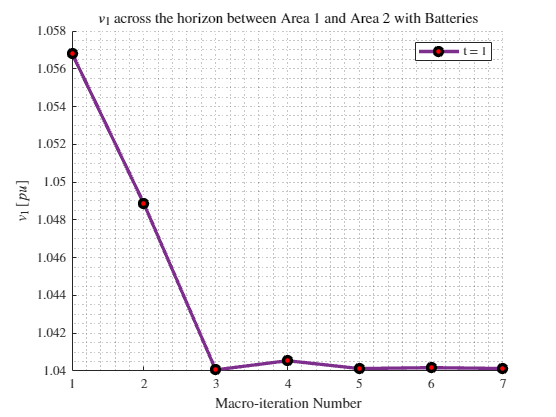

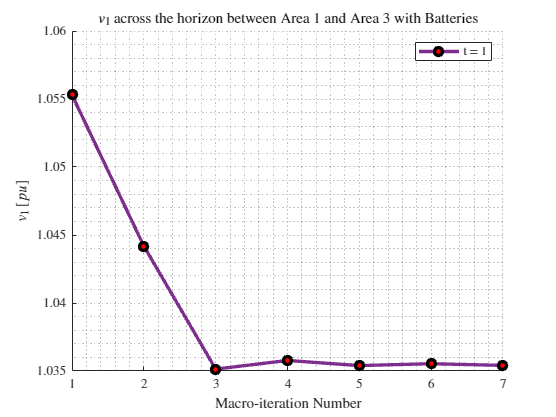

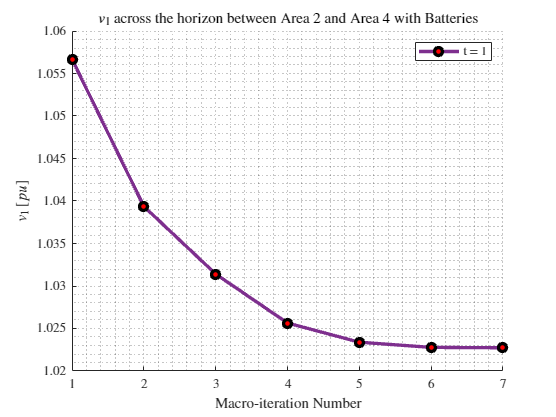

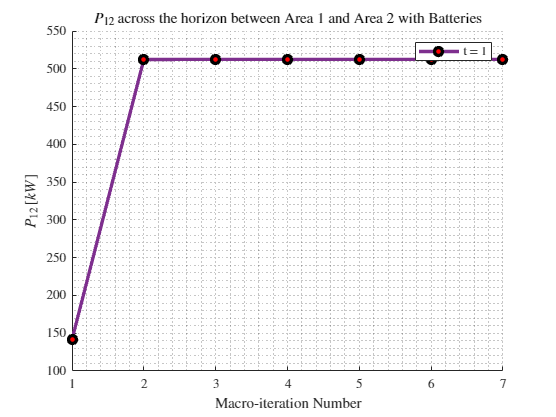

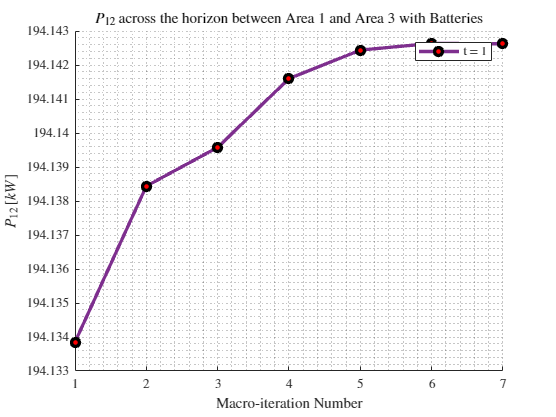

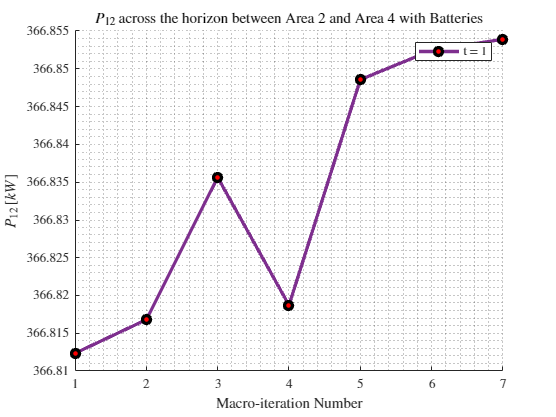

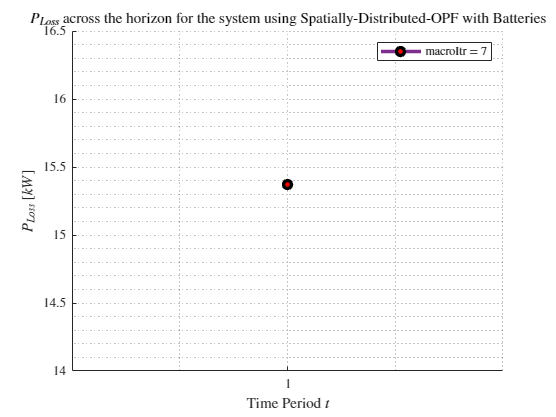

PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr(1:macroItr+1);
PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr(:, 1:macroItr+1);
PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr(1:macroItr+1);
PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr(:, 1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
results.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
restuls.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;


results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;
% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results, simInfo, sysInfo)

grandTotalTime = toc(start)

grandTotalTime = 263.4575

    
lineLoss_kW = 0;
genCost_dollars = 0;

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW = lineLoss_kW + lineLoss_Area_kW;

    genCost_Area_dollars = areaInfo.PSubsCost_allT * 1e-2;
    genCost_dollars = genCost_dollars + genCost_Area_dollars;

end
area1Info = sysInfo.Area{1};

substationPower_kW = sum(area1Info.P_Area_1toT(1, :))*kVA_B;

maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 1


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['Line Loss: ', num2str(lineLoss_kW),' kW'])                       

Line Loss: 15.3702 kW


disp(['Substation Power: ', num2str(substationPower_kW),' kW'])

Substation Power: 911.0117 kW


disp(['Substation Power Cost: ', num2str(genCost_dollars), ' $'])

Substation Power Cost: 69.4552 $


disp(['Number of Macro-Iterations: ', num2str(macroItr)])

Number of Macro-Iterations: 6


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 263.4575 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 165.1717 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 102.9517 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));
% systemSolutionName_x = strcat(prefixName, '_optimalSolutions.csv'); % For CSV file

% Determine the string based on whether batteries are included
if ~noBatteries
    battstring = 'withBatteries';
else
    battstring = 'withoutBatteries';
end

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW);
fprintf(fileID, 'Substation Power Cost: %.3f $\n', genCost_dollars);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s\n'));
fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_1_ETRL204-ARYAN_results_withBatteries.txt"

